%该文件用来绘制影长随经度度的变化图

n=n_days(2015,10,22);%根据自定义函数求得n

phi=((39+54/60+26/3600)/180)*2*pi;%由题，北京纬度为39度54分26秒
t=12;%取北京时间12点作为参考量
loit=-180:180;
delte=abs((23.45*sin(2*pi*(284+n)/365))/180)*2*pi;%delte为太阳赤纬
L=3;%表示直杆长度

l=zeros(1,size(loit,2));%用来存储所求的所有影长
for i=1:size(loit,2) 
    st_t=t-8+loit(i)/15;%根据自定义函数转化为当地标准时间
    H=((15*(st_t-12))/180)*2*pi;%H为太阳时角
    alpha=asin(sin(delte)*sin(phi)+cos(delte)*cos(phi)*cos(H));%alpha为太阳光线的入射角度
    l(1,i)=abs(L/tan(alpha));%l表示此时影长
end
[lmax,indax]=max(l)

lmax =   12.016464279540797


indax =     31


[lmin,indin]=min(l)

lmin =    4.383213872039006


indin =    121


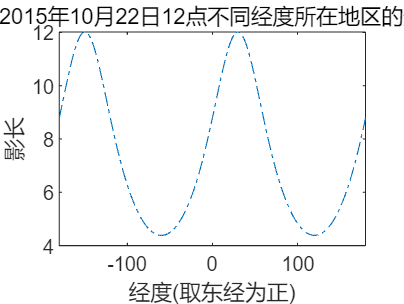


figure(1)
plot(loit,l,'-.');
title('北京时间2015年10月22日12点不同经度所在地区的影长变化图');
xlabel('经度(取东经为正)');
ylabel('影长');
xlim([-180,180]);